I = imread('rice.png');
figure; 
imshow(I); 
hold on;

x1 = 150;
y1 = 200;

c1= 101;
c2= 202;

A = [x1 c1];
B = [y1 c2];

plot(A,B,'*')

coefficients = polyfit(A, B, 1);
a = coefficients (1);
b = coefficients (2);

aLine = [a,-1,b];



points = lineToBorderPoints(aLine,size(I))

points =     0.5000  206.1020  256.5000  195.6531


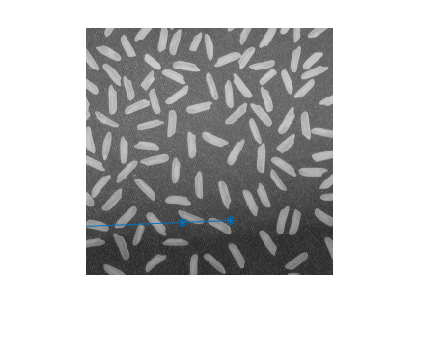


% distance2Border1 = [x1,y1;points(1),points(2)];
distance2Border2 = pdist([x1,y1;points(3),points(4)],'euclidean');
distance_C2Border = pdist([points(3),points(4);c1,c2],'euclidean');




if distance2Border2 > distance_C2Border

    line([x1,points(3)],[y1,points(4)]);
else
    line([x1,points(1)],[y1,points(2)]);
end